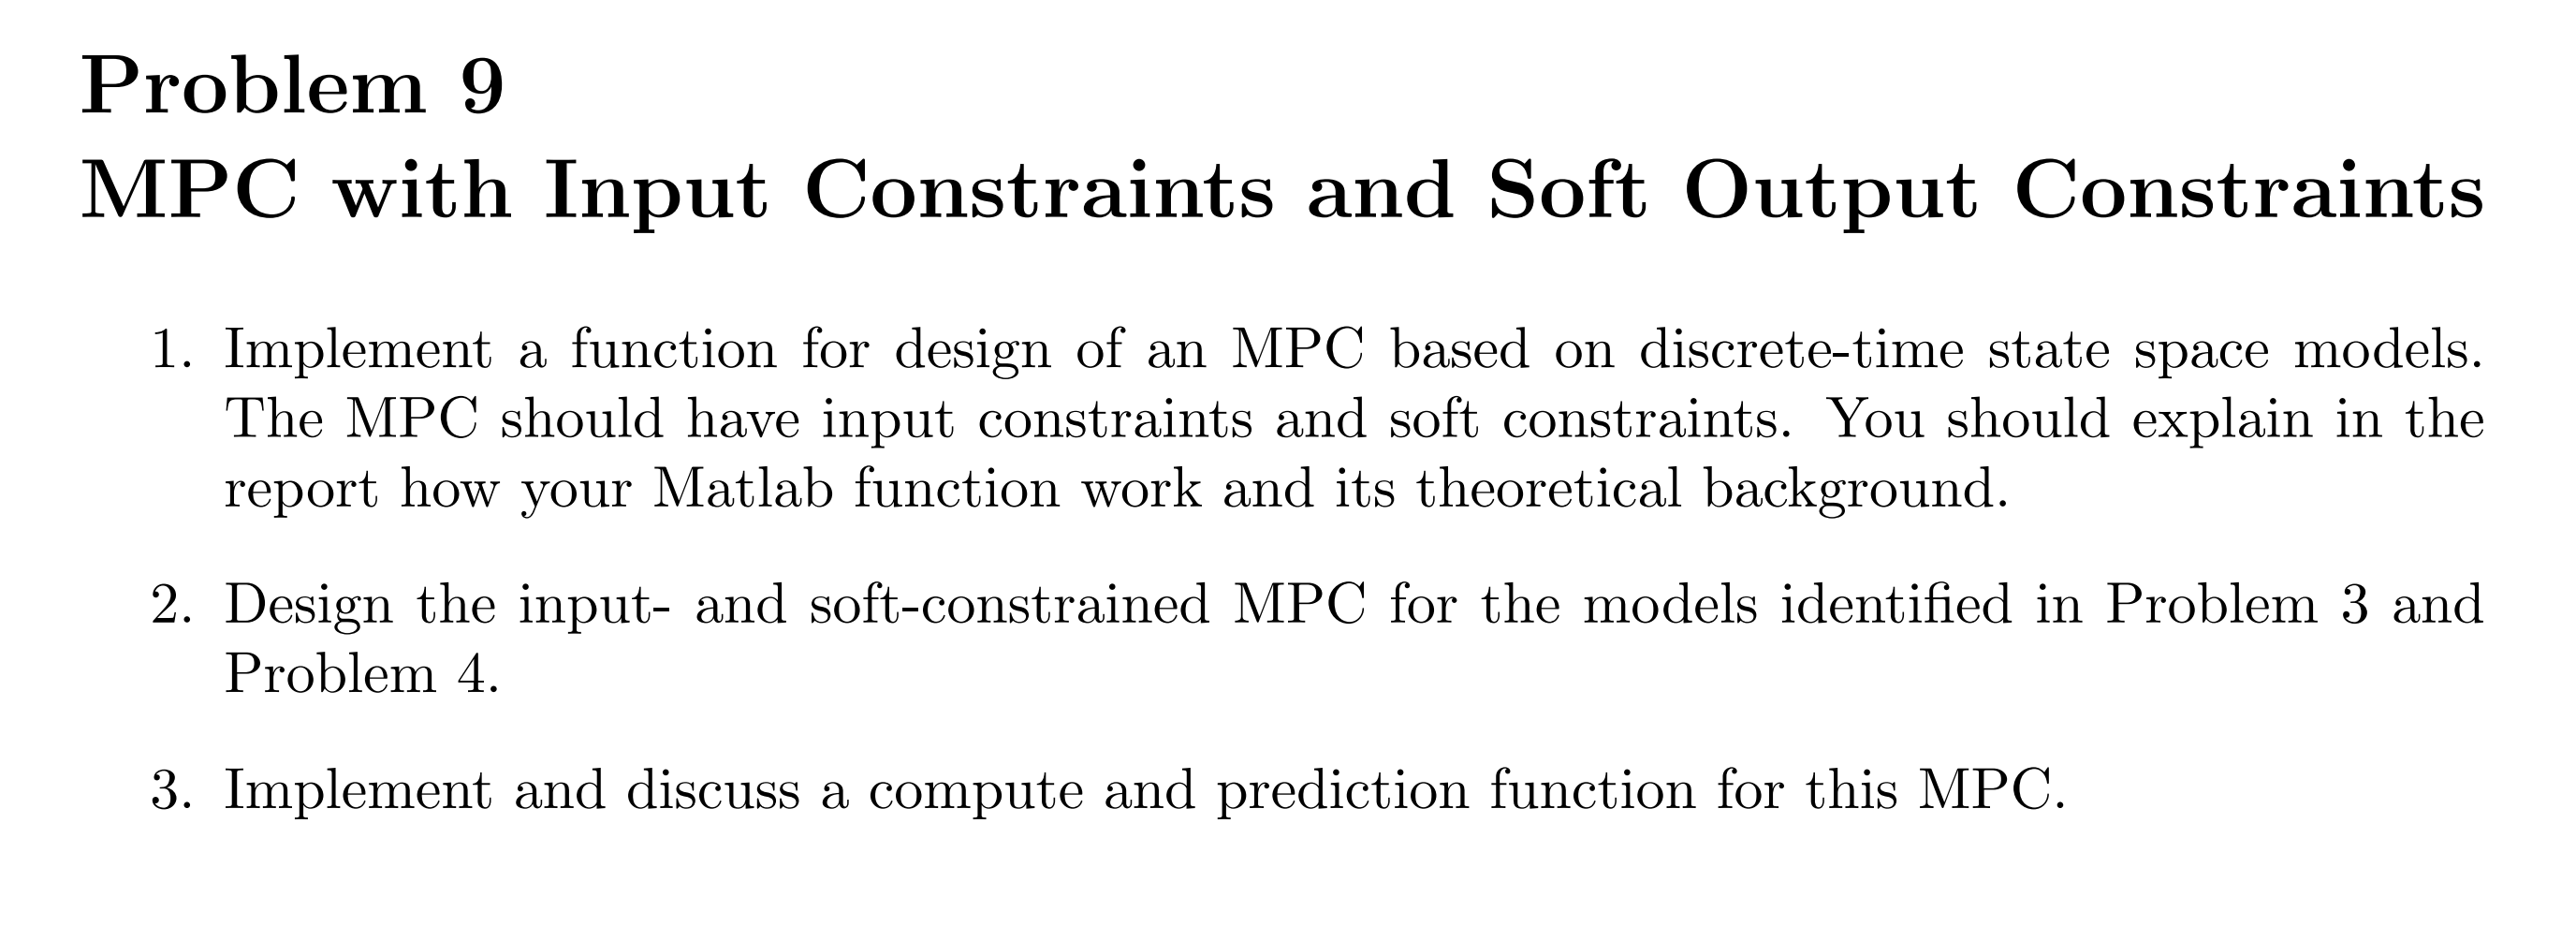

% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1
a2 = 1.2272 %[cm2] Area of outlet pipe 2
a3 = 1.2272 %[cm2] Area of outlet pipe 3 1.2272
a4 = 1.2272 %[cm2] Area of outlet pipe 4
A1 = 380.1327 %[cm2] Cross sectional area of tank 1
A2 = 380.1327 %[cm2] Cross sectional area of tank 2
A3 = 380.1327 %[cm2] Cross sectional area of tank 3 380
A4 = 380.1327 %[cm2] Cross sectional area of tank 4
gamma1 = 0.45; % Flow distribution constant. Valve 1 0.45
gamma2 = 0.40; % Flow distribution constant. Valve 2 0.40
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------
%a3 a4:1.2272 Non-minimum phase system
%a3 a4:8 Minimum phase system

%steady-state
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)
ys = FourTankSystemSensor(xs,p)
zs = FourTankSystemOutput(xs,p)

syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))
Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))
Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))
Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))
Czss=Css(1:2,:)
Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))
Dzss=Dss(1:2,:)

%Compute discrete-time state space models
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts)
[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts)
Gw_d=Bd_d;

%kalman static observer design based on the problem4
Ad_kf=[Ad,Bd_d;zeros(2,4),eye(2,2)];
Bd_kf=[Bd;zeros(2,2)];
Cd_kf=[Czss,zeros(2,2)];
Cdy_kf=[Css,zeros(4,2)];
W_kf=diag([1 1 1 1 0.002 0.002])*Ts
V_kf=diag([1 1]);
Vy_kf=diag([1 1 1 1])
G_w=[diag([1 1 1 1]),Bd_d;zeros(2,4),eye(2,2)];
Mr = ctrb(Ad_kf,Bd_kf);
if rank(Mr) == size(Ad_kf,1)
    disp('The open loop system is reachable')
end
% Check observability
Mo = obsv(Ad_kf,Cd_kf);
if rank(Mo) == size(Ad_kf,1)
    disp('The open loop system is observable')
end
% Design of the discrete time closed form Kalman filter

[L_kf,P_kf,Qe_th,lamda_kf_d] = dlqe(Ad_kf,G_w,Cdy_kf,W_kf,Vy_kf)

%MPC with Input Constraints and Soft Output Constraints tested in linear model without step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
%step 0.05
d = [repmat(50,1,N); repmat(50,1,N)];
%d(1,index_step:end)=100;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;
ref=80;
N_pre=50;
u_min=0;
u_max=600;
u_delta_min=-30;
u_delta_max=30;
z_min=[-1000;-1000;-1000;-1000];
z_min_error=[-1000;ref-10;-1000;-1000];%-10
z_min_safe=[0;0;0;0];
z_max=[ref+10;ref+1000;ref+1000;ref+1000];%+10
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);
y_bar = zeros(num_y,N);
x0=zeros(4,1);
d0=zeros(2,1);
y0=zeros(4,1);
x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
y_bar(:,1) = y0;
xk=x_bar(:,1);

rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
dk=d_bar(:,1);
uk=zeros(num_u,1);%d1,d2 ref
xk=x0;
usk=repmat(us(1),N_pre*num_u,1);
Q_cof=0.03;
u_delta_cof=10;
eta_cof1=10;%zmin 
eta_cof2=10;%zmax 
z_flag=0;
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function

%%%%%%%%%%%%%%kalman observer%%%%%%%%%%%%%%
%static kalman
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+Ad_kf*L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
Y_bar=Cdy_kf*x_kf;
xk = x_kf(1:num_x);
%dk = [repmat(x_kf(num_x+1),N_pre,1); repmat(x_kf(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% Y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-Y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);
%%%%%%%%%%%%%%%decision making%%%%%%%%%%%
if(yk(2)>(z_min_error(2)-5))
    z_min=z_min_error;
    z_flag=1;
else 
    z_min=z_min_safe; 
end
if(z_flag==1)
    z_min=z_min_error;
end
%%%%%%%%%%%%%%%MPC controller%%%%%%%%%%%%%% 
tic;
uk=LMPCcompute_inputcons_outputSoftCons(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof1,eta_cof2);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);
x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;
u(:,k+1)=uk;
x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
y_bar(:,k+1) = Y_bar;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

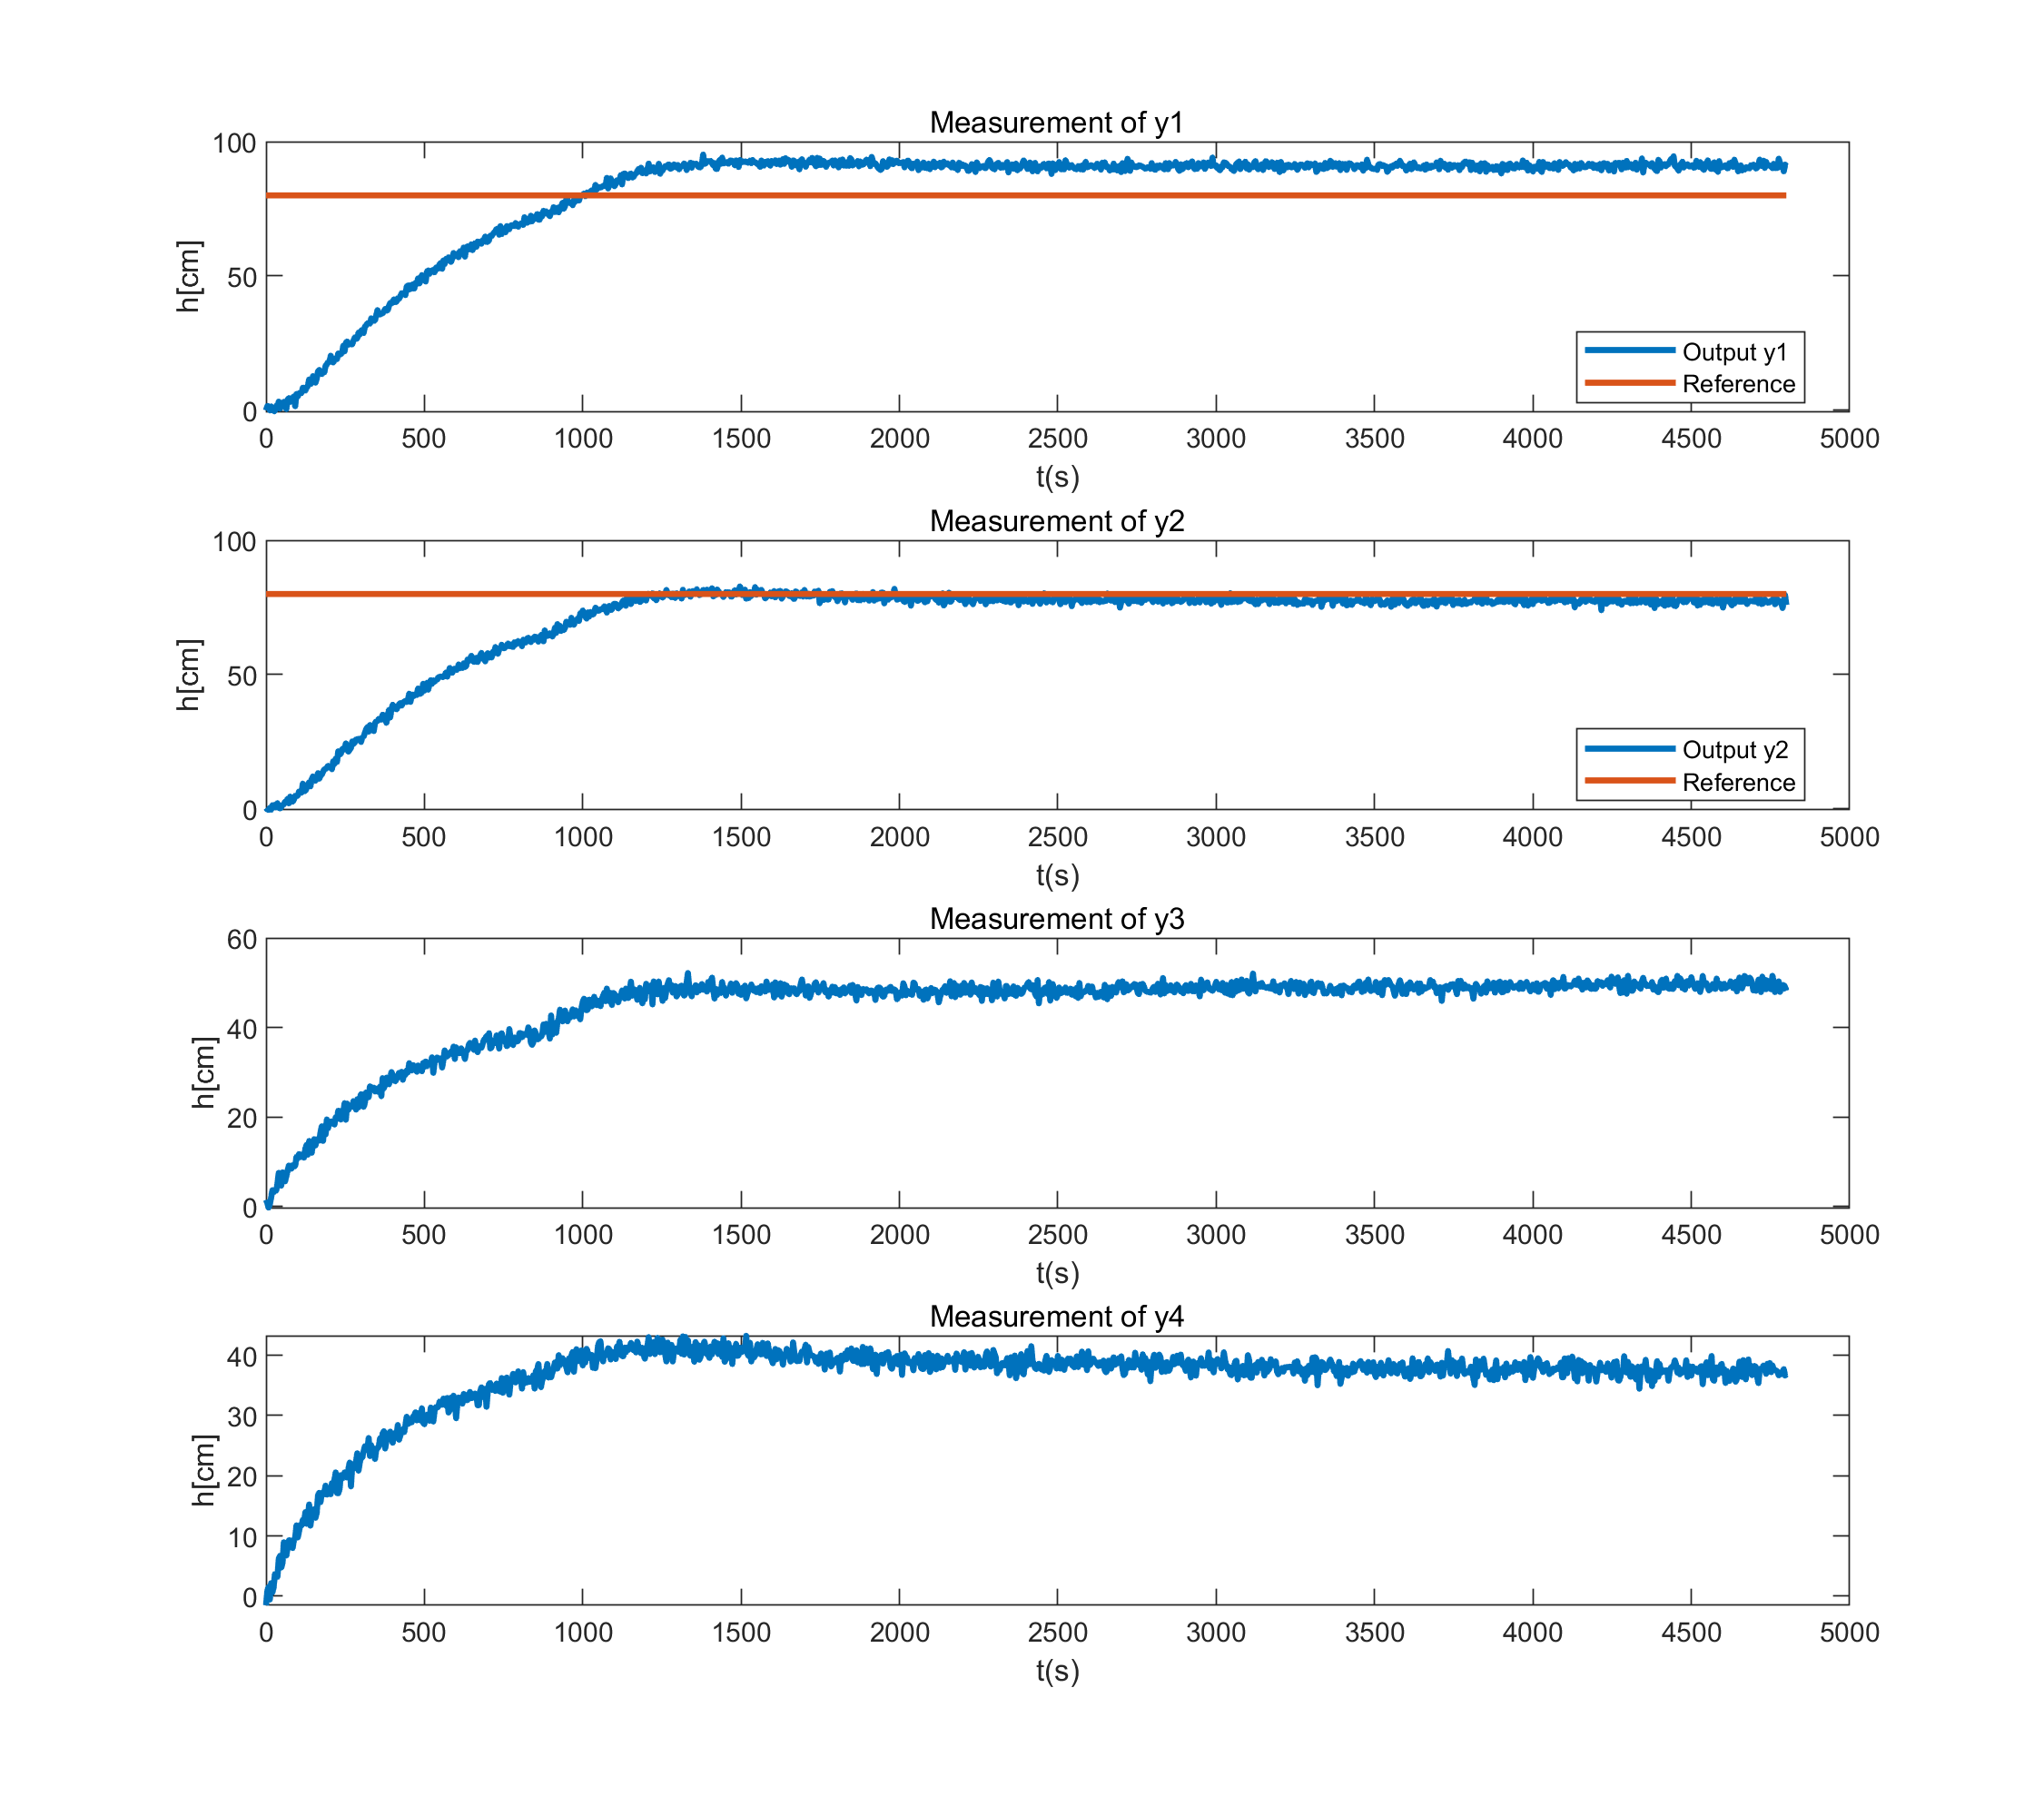

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

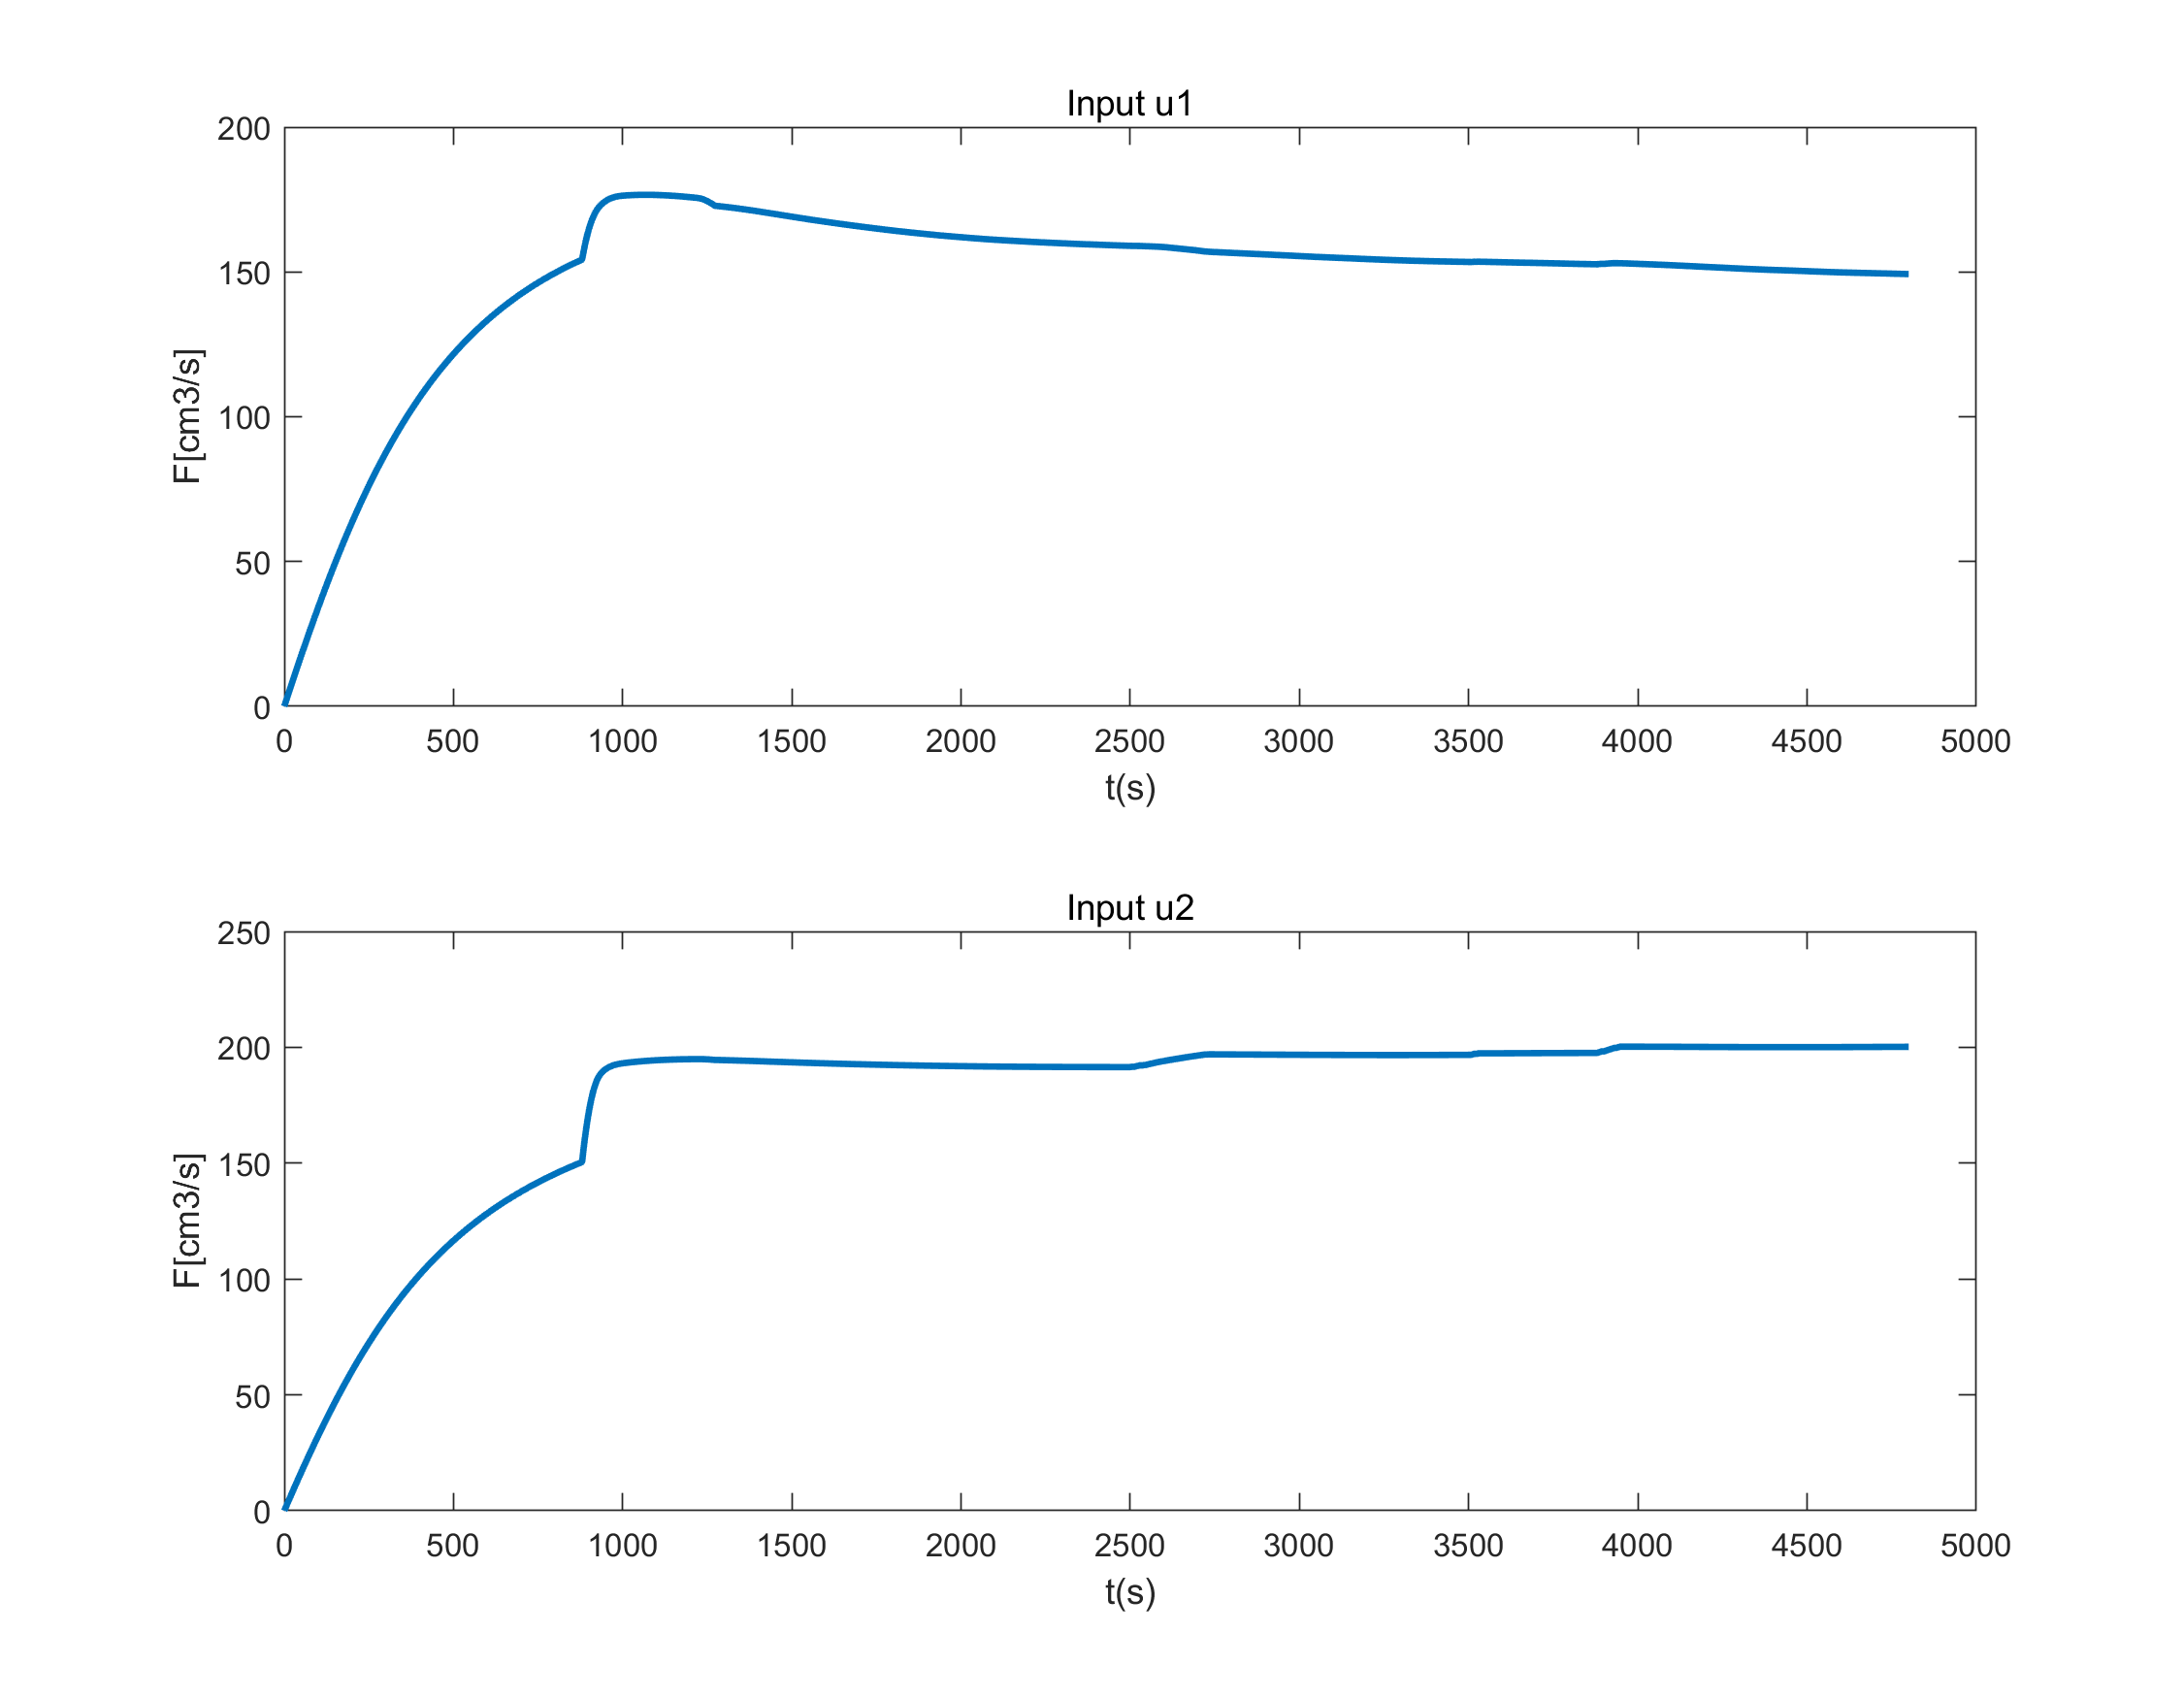

% ylim([0,20]);



figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

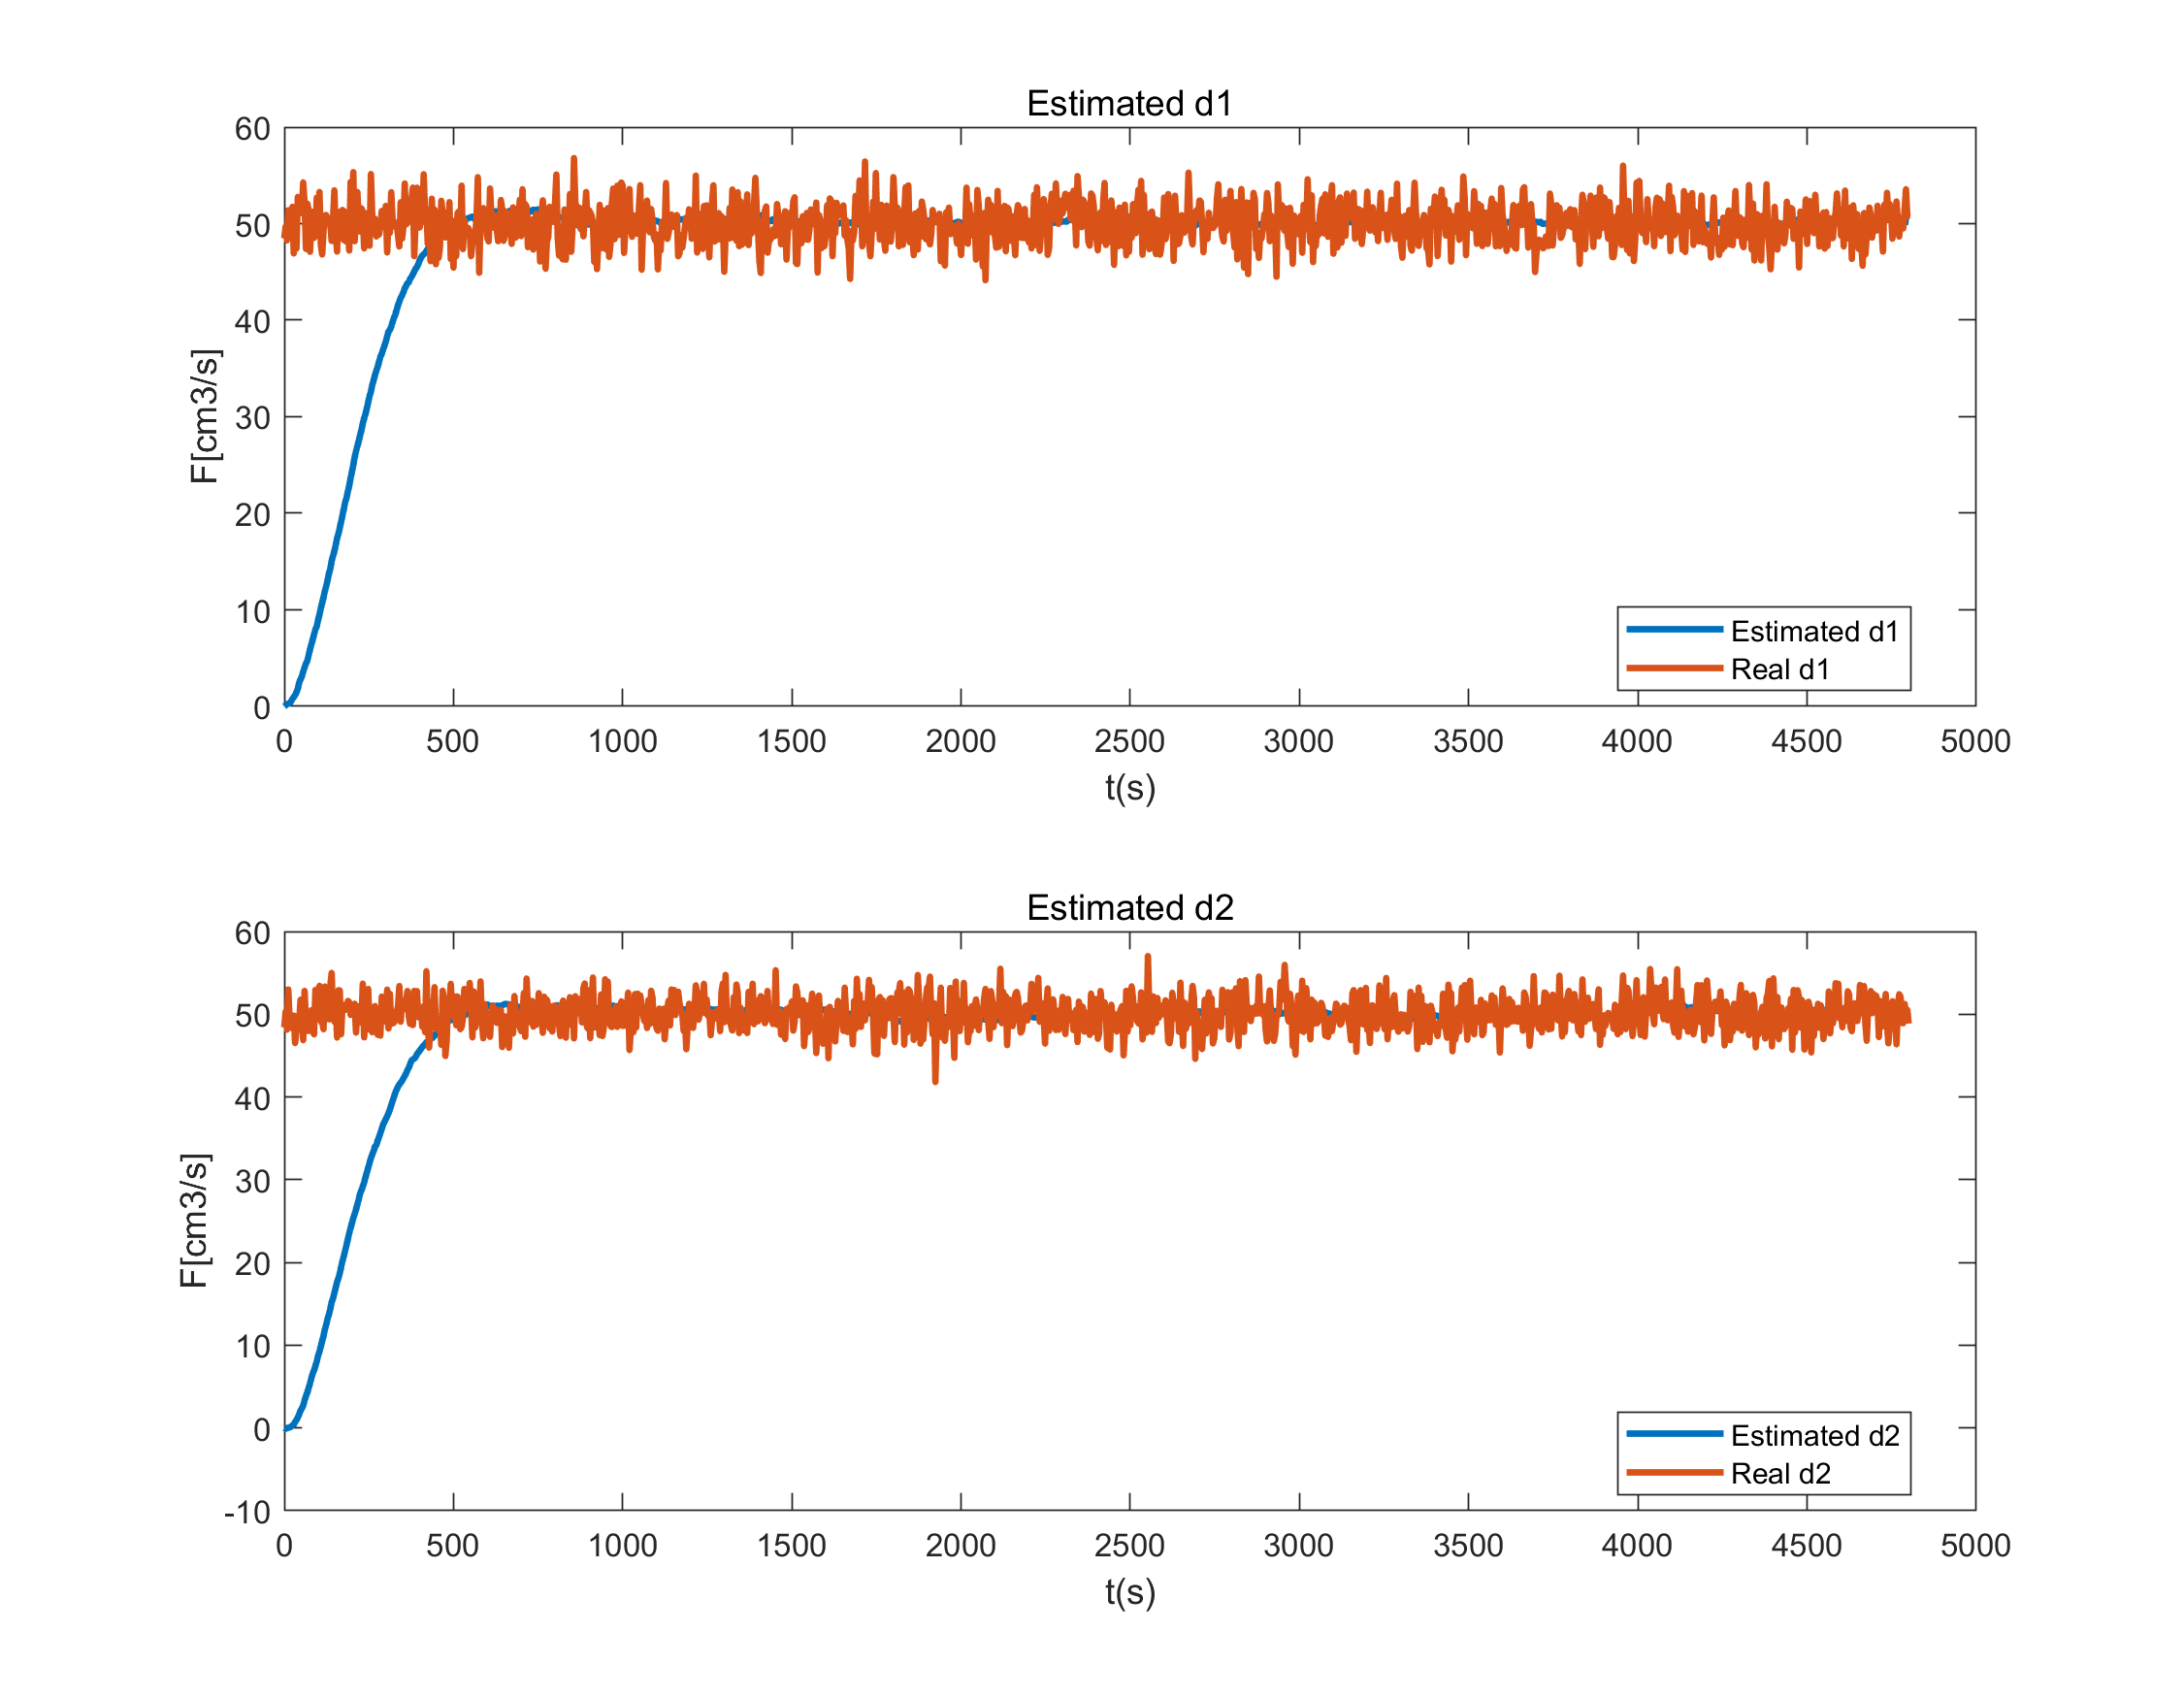

%ylim([0,40]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,d_bar(1,:),t,dw(1,:),'LineWidth',2.0)
title('Estimated d1')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d1","Real d1","Location", 'best');
%ylim([0,40]);
subplot(2,1,2)
plot(t,d_bar(2,:),t,dw(2,:),'LineWidth',2.0)
title('Estimated d2')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d2","Real d2","Location", 'best');

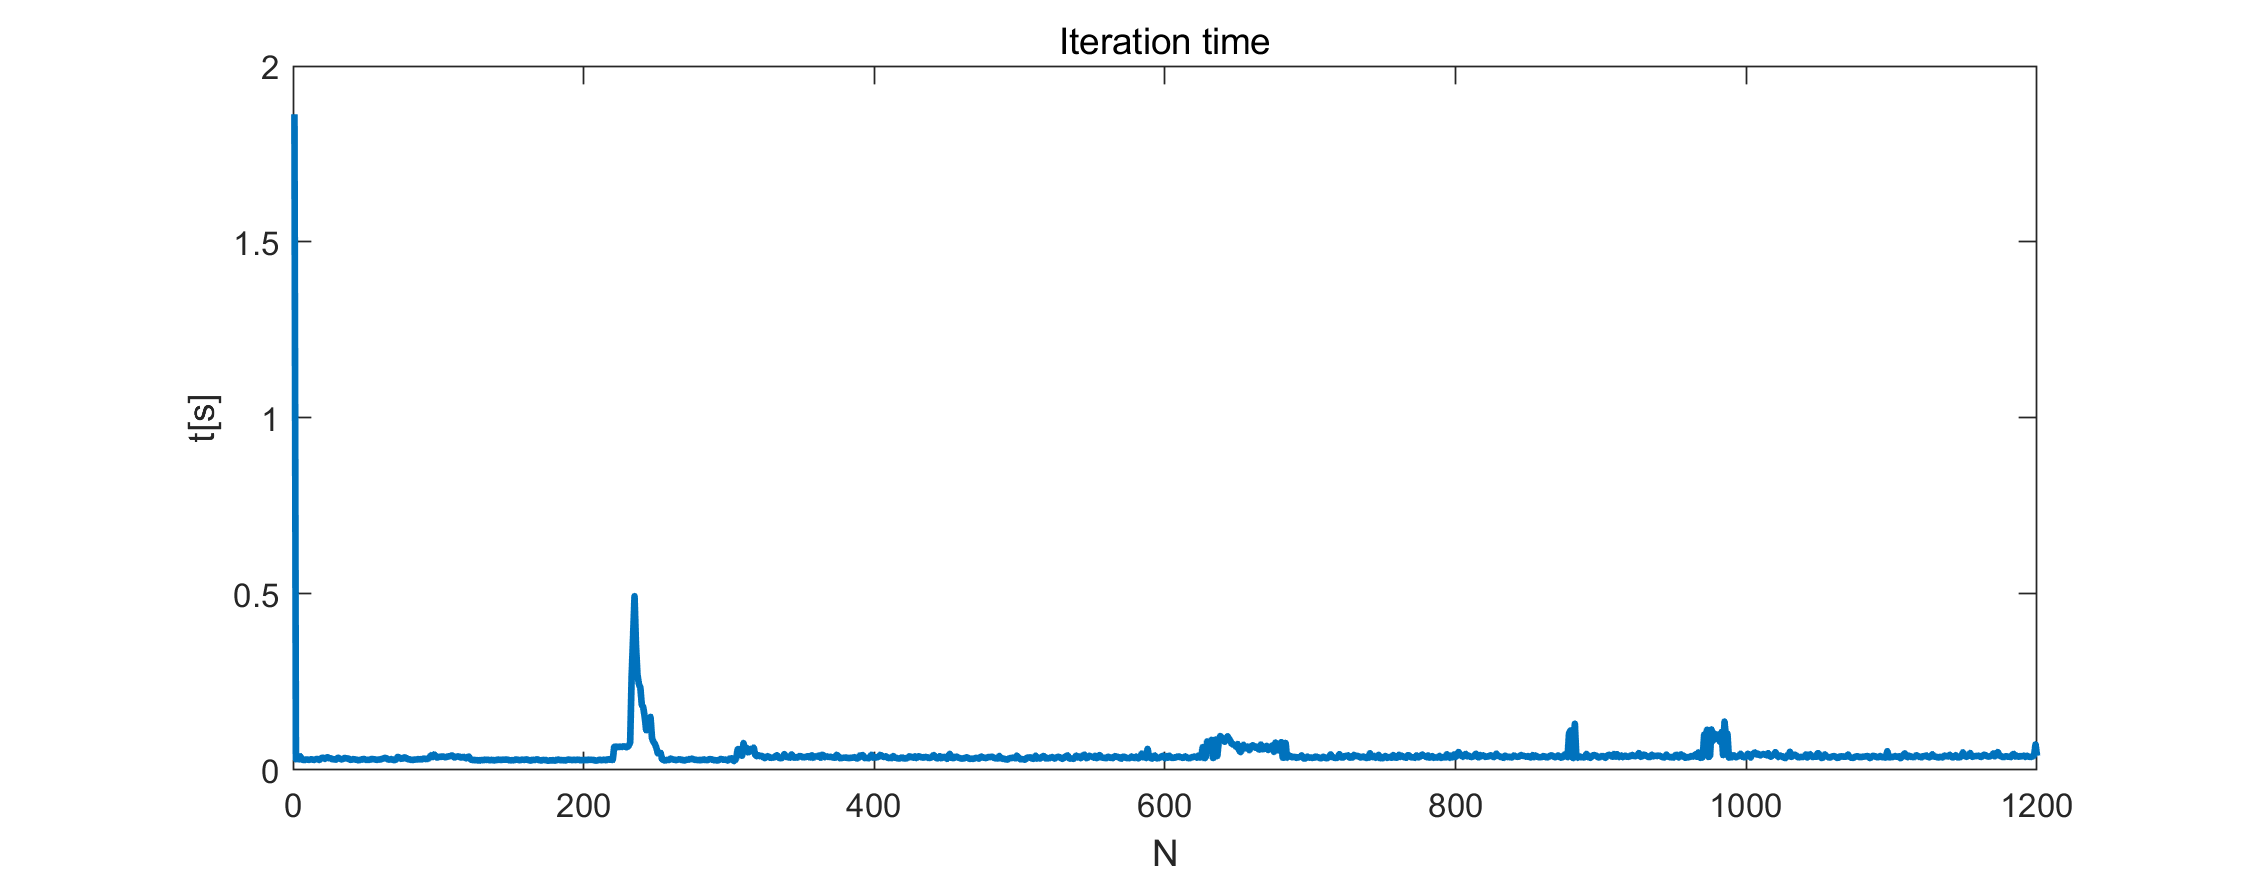

%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%MPC with Input Constraints and Soft Output Constraints tested in linear model with step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
%step 0.05
d = [repmat(50,1,N); repmat(50,1,N)];
d(1,index_step:end)=100;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;
ref=80;
N_pre=50;
u_min=0;
u_max=600;
u_delta_min=-30;
u_delta_max=30;
z_min=[-1000;-1000;-1000;-1000];
z_min_error=[-1000;ref-10;-1000;-1000];%-10
z_min_safe=[0;0;0;0];
z_max=[ref+10;ref+1000;ref+1000;ref+1000];%+10
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);
y_bar = zeros(num_y,N);
x0=zeros(4,1);
d0=zeros(2,1);
y0=zeros(4,1);
x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
y_bar(:,1) = y0;
xk=x_bar(:,1);

rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
dk=d_bar(:,1);
uk=zeros(num_u,1);%d1,d2 ref
xk=x0;
usk=repmat(us(1),N_pre*num_u,1);
Q_cof=0.03;
u_delta_cof=10;
eta_cof1=10;%zmin 
eta_cof2=10;%zmax 
z_flag=0;
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%
yk=Css*xk+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function

%%%%%%%%%%%%%%kalman observer%%%%%%%%%%%%%%
%static kalman
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+Ad_kf*L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
Y_bar=Cdy_kf*x_kf;
xk = x_kf(1:num_x);
%dk = [repmat(x_kf(num_x+1),N_pre,1); repmat(x_kf(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% Y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-Y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);
%%%%%%%%%%%%%%%decision making%%%%%%%%%%%
if(yk(2)>(z_min_error(2)-5))
    z_min=z_min_error;
    z_flag=1;
else 
    z_min=z_min_safe; 
end
if(z_flag==1)
    z_min=z_min_error;
end
%%%%%%%%%%%%%%%MPC controller%%%%%%%%%%%%%% 
tic;
uk=LMPCcompute_inputcons_outputSoftCons(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof1,eta_cof2);
elapsedTime = toc;
t_record=[t_record;elapsedTime];
%state update
xk=Ad*x(:,k)+Bd*uk+Bd_d*d(:,k)+Gw_d*w(:,k);
x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;
u(:,k+1)=uk;
x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
y_bar(:,k+1) = Y_bar;
end
k=N;
yk=Css*x(:,k)+Dss*uk+v_low(:,k); % Sensor function
yk_no_noise=Css*xk+Dss*uk;
zk=yk_no_noise(1:2,:); % Output function
y(:,k)=yk;
z(:,k)=zk;

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);



figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,d_bar(1,:),t,dw(1,:),'LineWidth',2.0)
title('Estimated d1')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d1","Real d1","Location", 'best');
%ylim([0,40]);
subplot(2,1,2)
plot(t,d_bar(2,:),t,dw(2,:),'LineWidth',2.0)
title('Estimated d2')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d2","Real d2","Location", 'best');
%ylim([0,40]);

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%MPC with Input Constraints and Soft Output Constraints tested in nonlinear model without step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(300,1,N); repmat(300,1,N)];
%d(1,index_step:end)=350;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;

ref=200;
N_pre=50;
u_min=0;
u_max=600;
u_delta_min=-30;
u_delta_max=30;
z_min=[-1000;-1000;-1000;-1000];
z_min_error=[-1000;ref-10;-1000;-1000];
z_min_safe=[0;0;0;0];
z_max=[ref+10;ref+1000;ref+1000;ref+1000];
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);

x0=xs;
d0=zeros(2,1);

x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
xk=x_bar(:,1);
rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
dk=d_bar(:,1);
uk=us;%d1,d2 ref
usk=[repmat(us(1),N_pre*num_u,1); zeros(N_pre*num_eta,1)];

x(:,1)=x0;
u(:,1)=uk;
z_flag=0;
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%%%%
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function

%%%%%%%%%%%%%%%%%%kalman observer%%%%%%%%%%%%%%%%%%
%static observer
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+Ad_kf*L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
xk = x_kf(1:num_x);
%dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% 
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);
%%%%%%%%%%%%%%decision making%%%%%%%%%%%%%%%%
if(yk(2)>(z_min_error(2)-10))
    z_min=z_min_error;
    z_flag=1;
else 
    z_min=z_min_safe; 
end
if(z_flag==1)
    z_min=z_min_error;
end
%%%%%%%%%%%%%%MPC controller%%%%%%%%%%%%%%%%
tic;
uk=LMPCcompute_inputcons_outputSoftCons(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof1,eta_cof2);
elapsedTime = toc;
t_record=[t_record;elapsedTime];

u(:,k+1)=uk;
%state update
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],uk,d(:,k)+w(:,k),p);
xk=Xk(end,:)';

x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;

x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

k=N;
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function
y(:,k)=yk;
z(:,k)=zk;

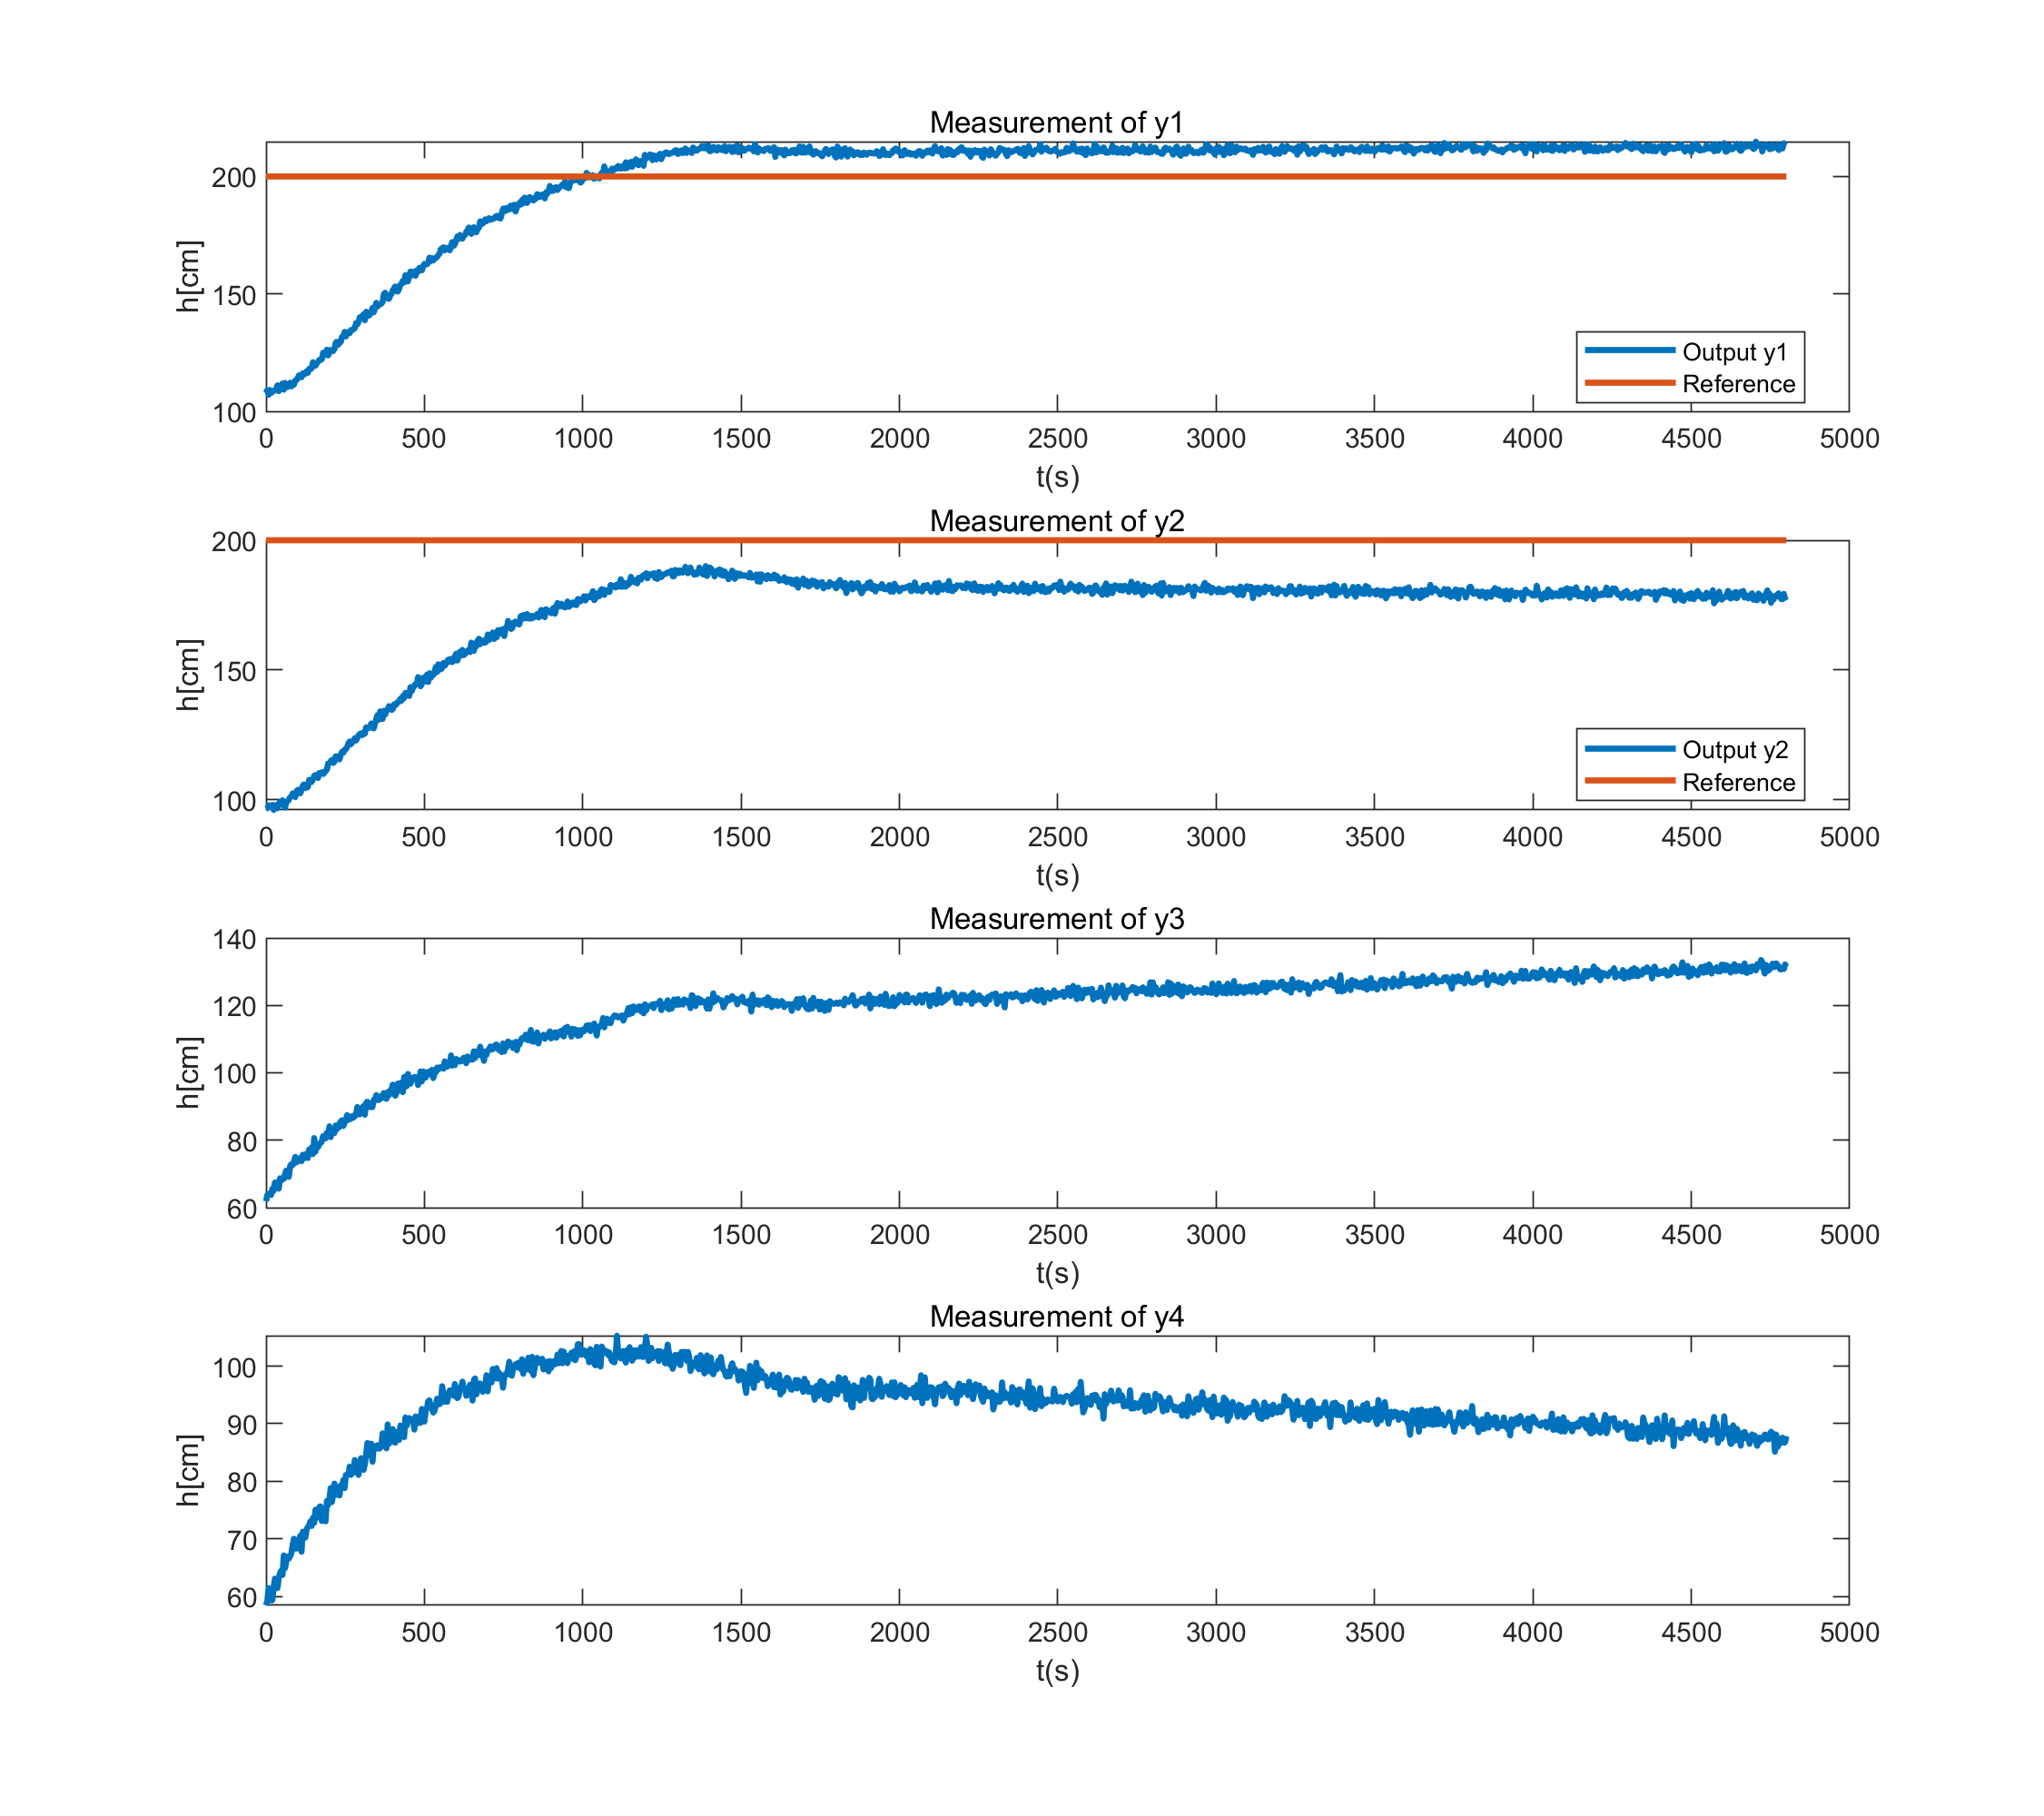

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');

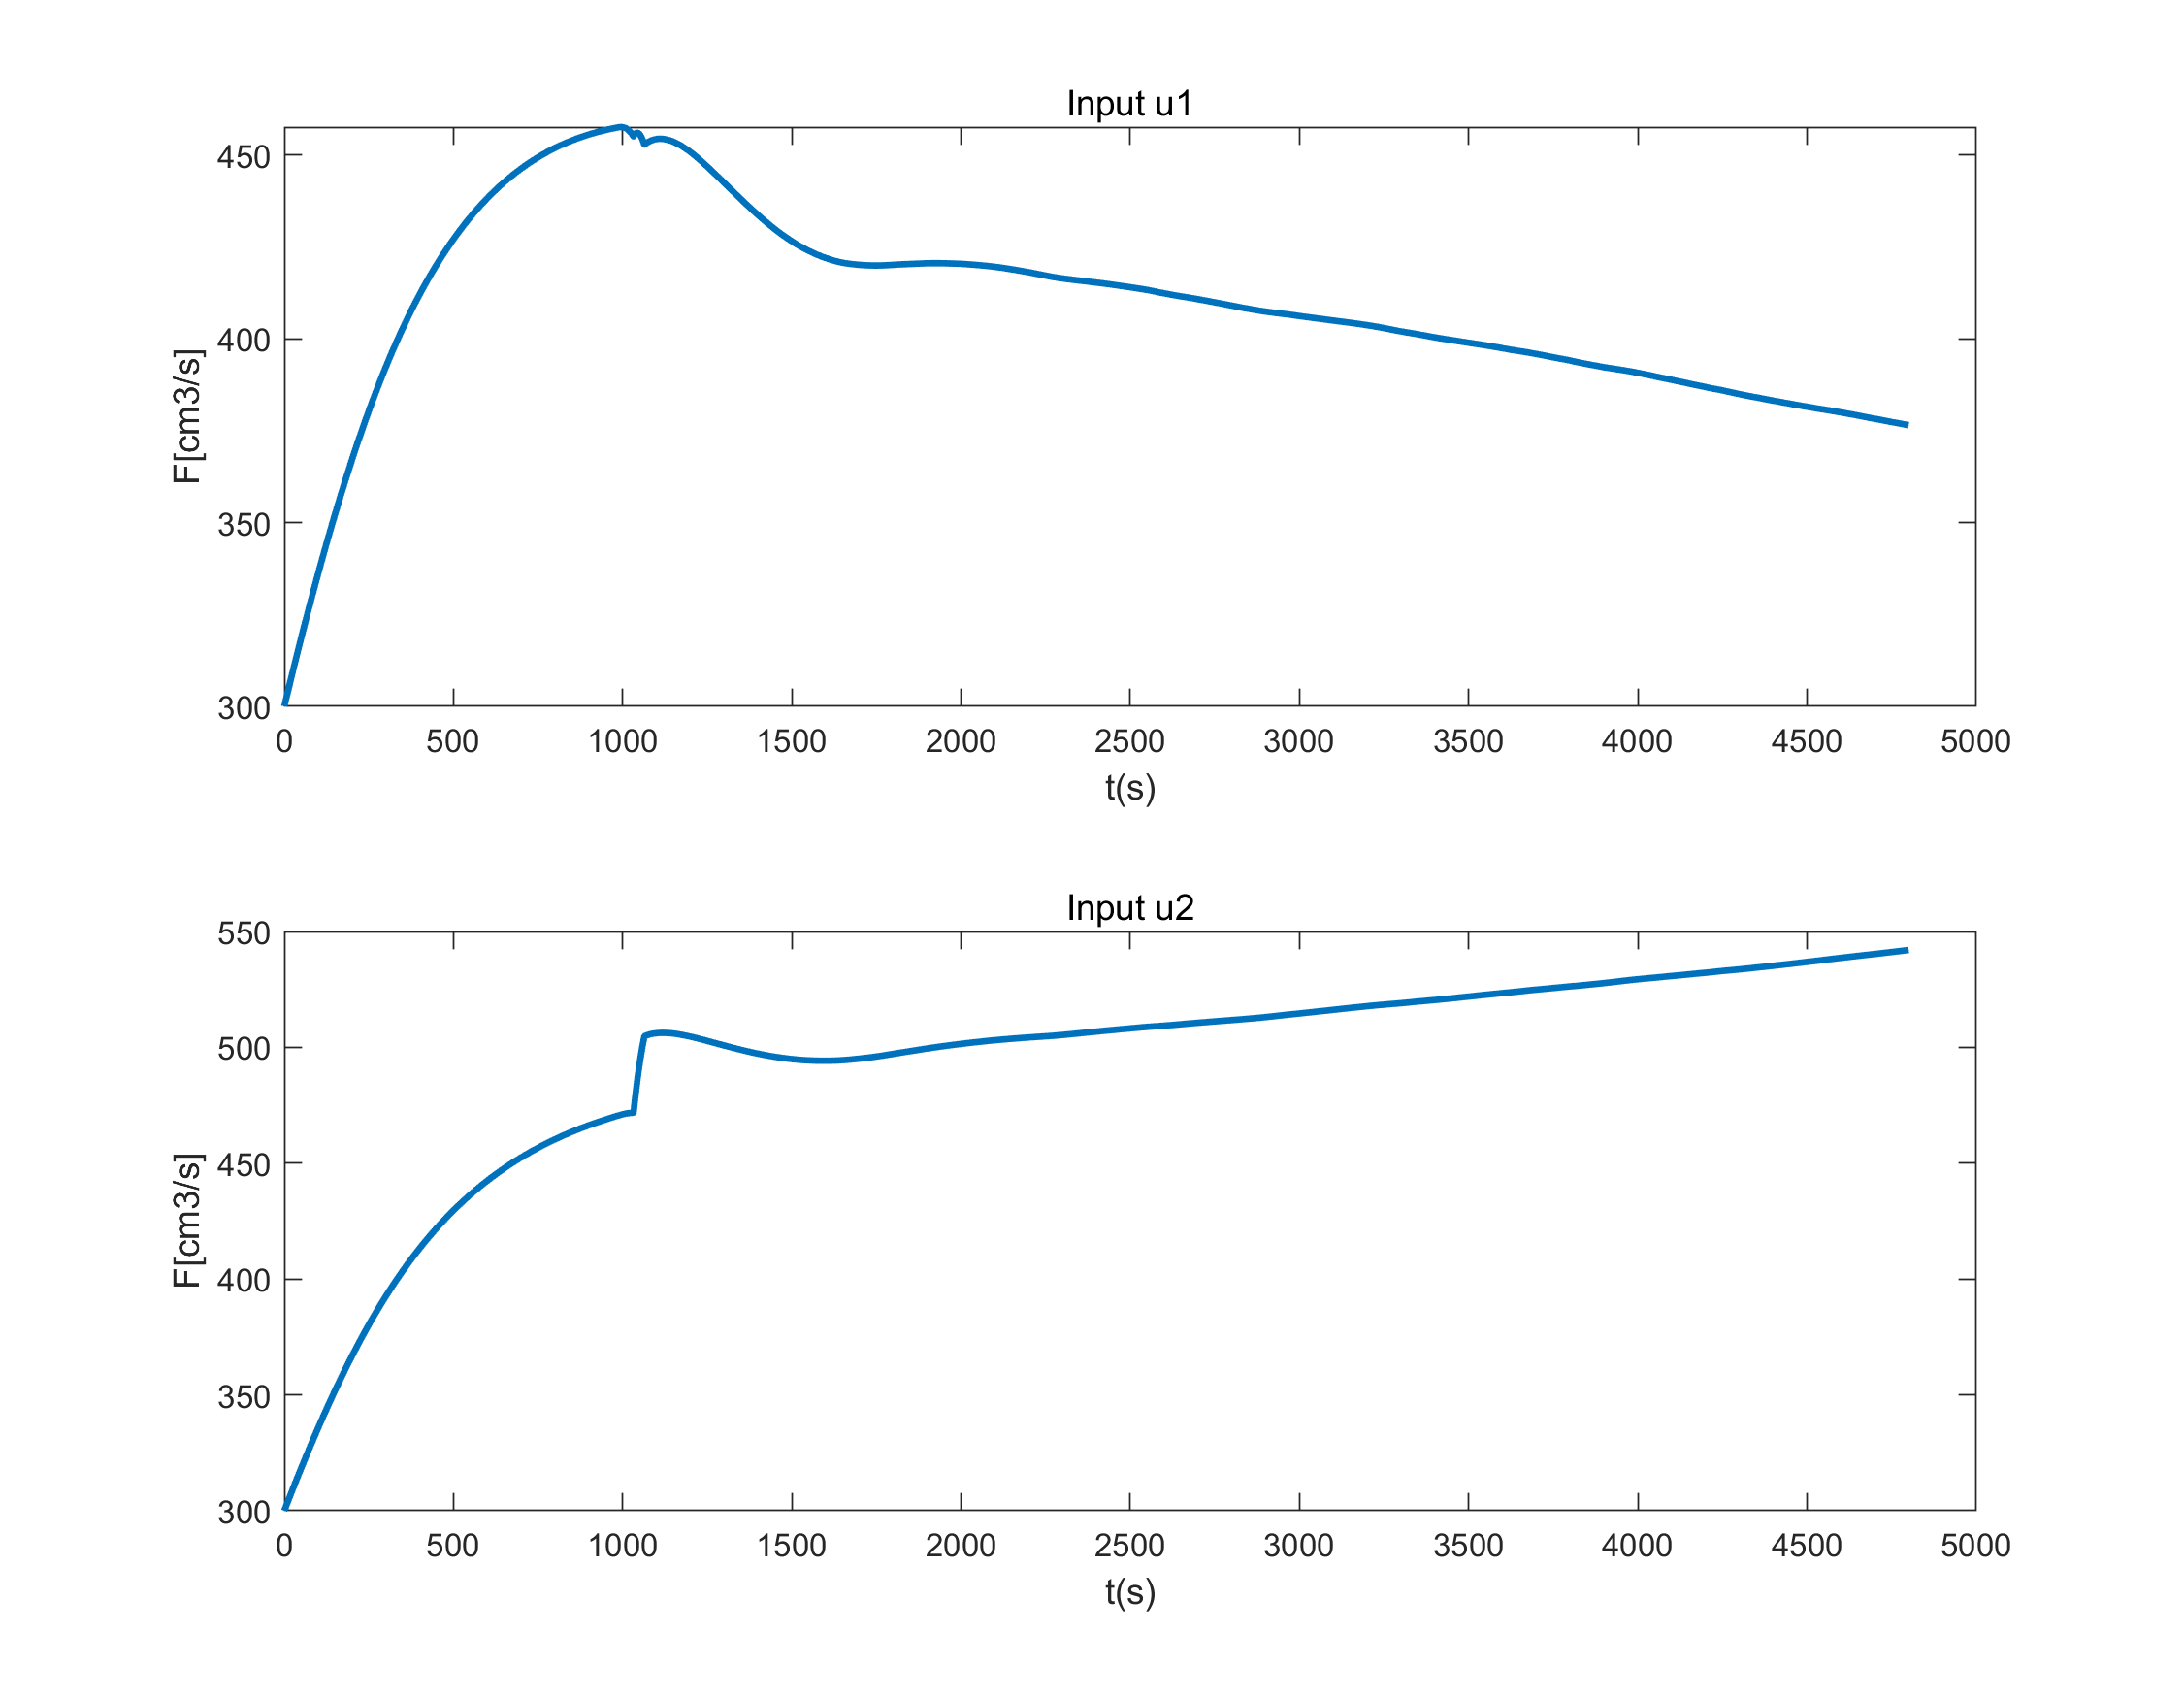

% ylim([0,20]);



figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');

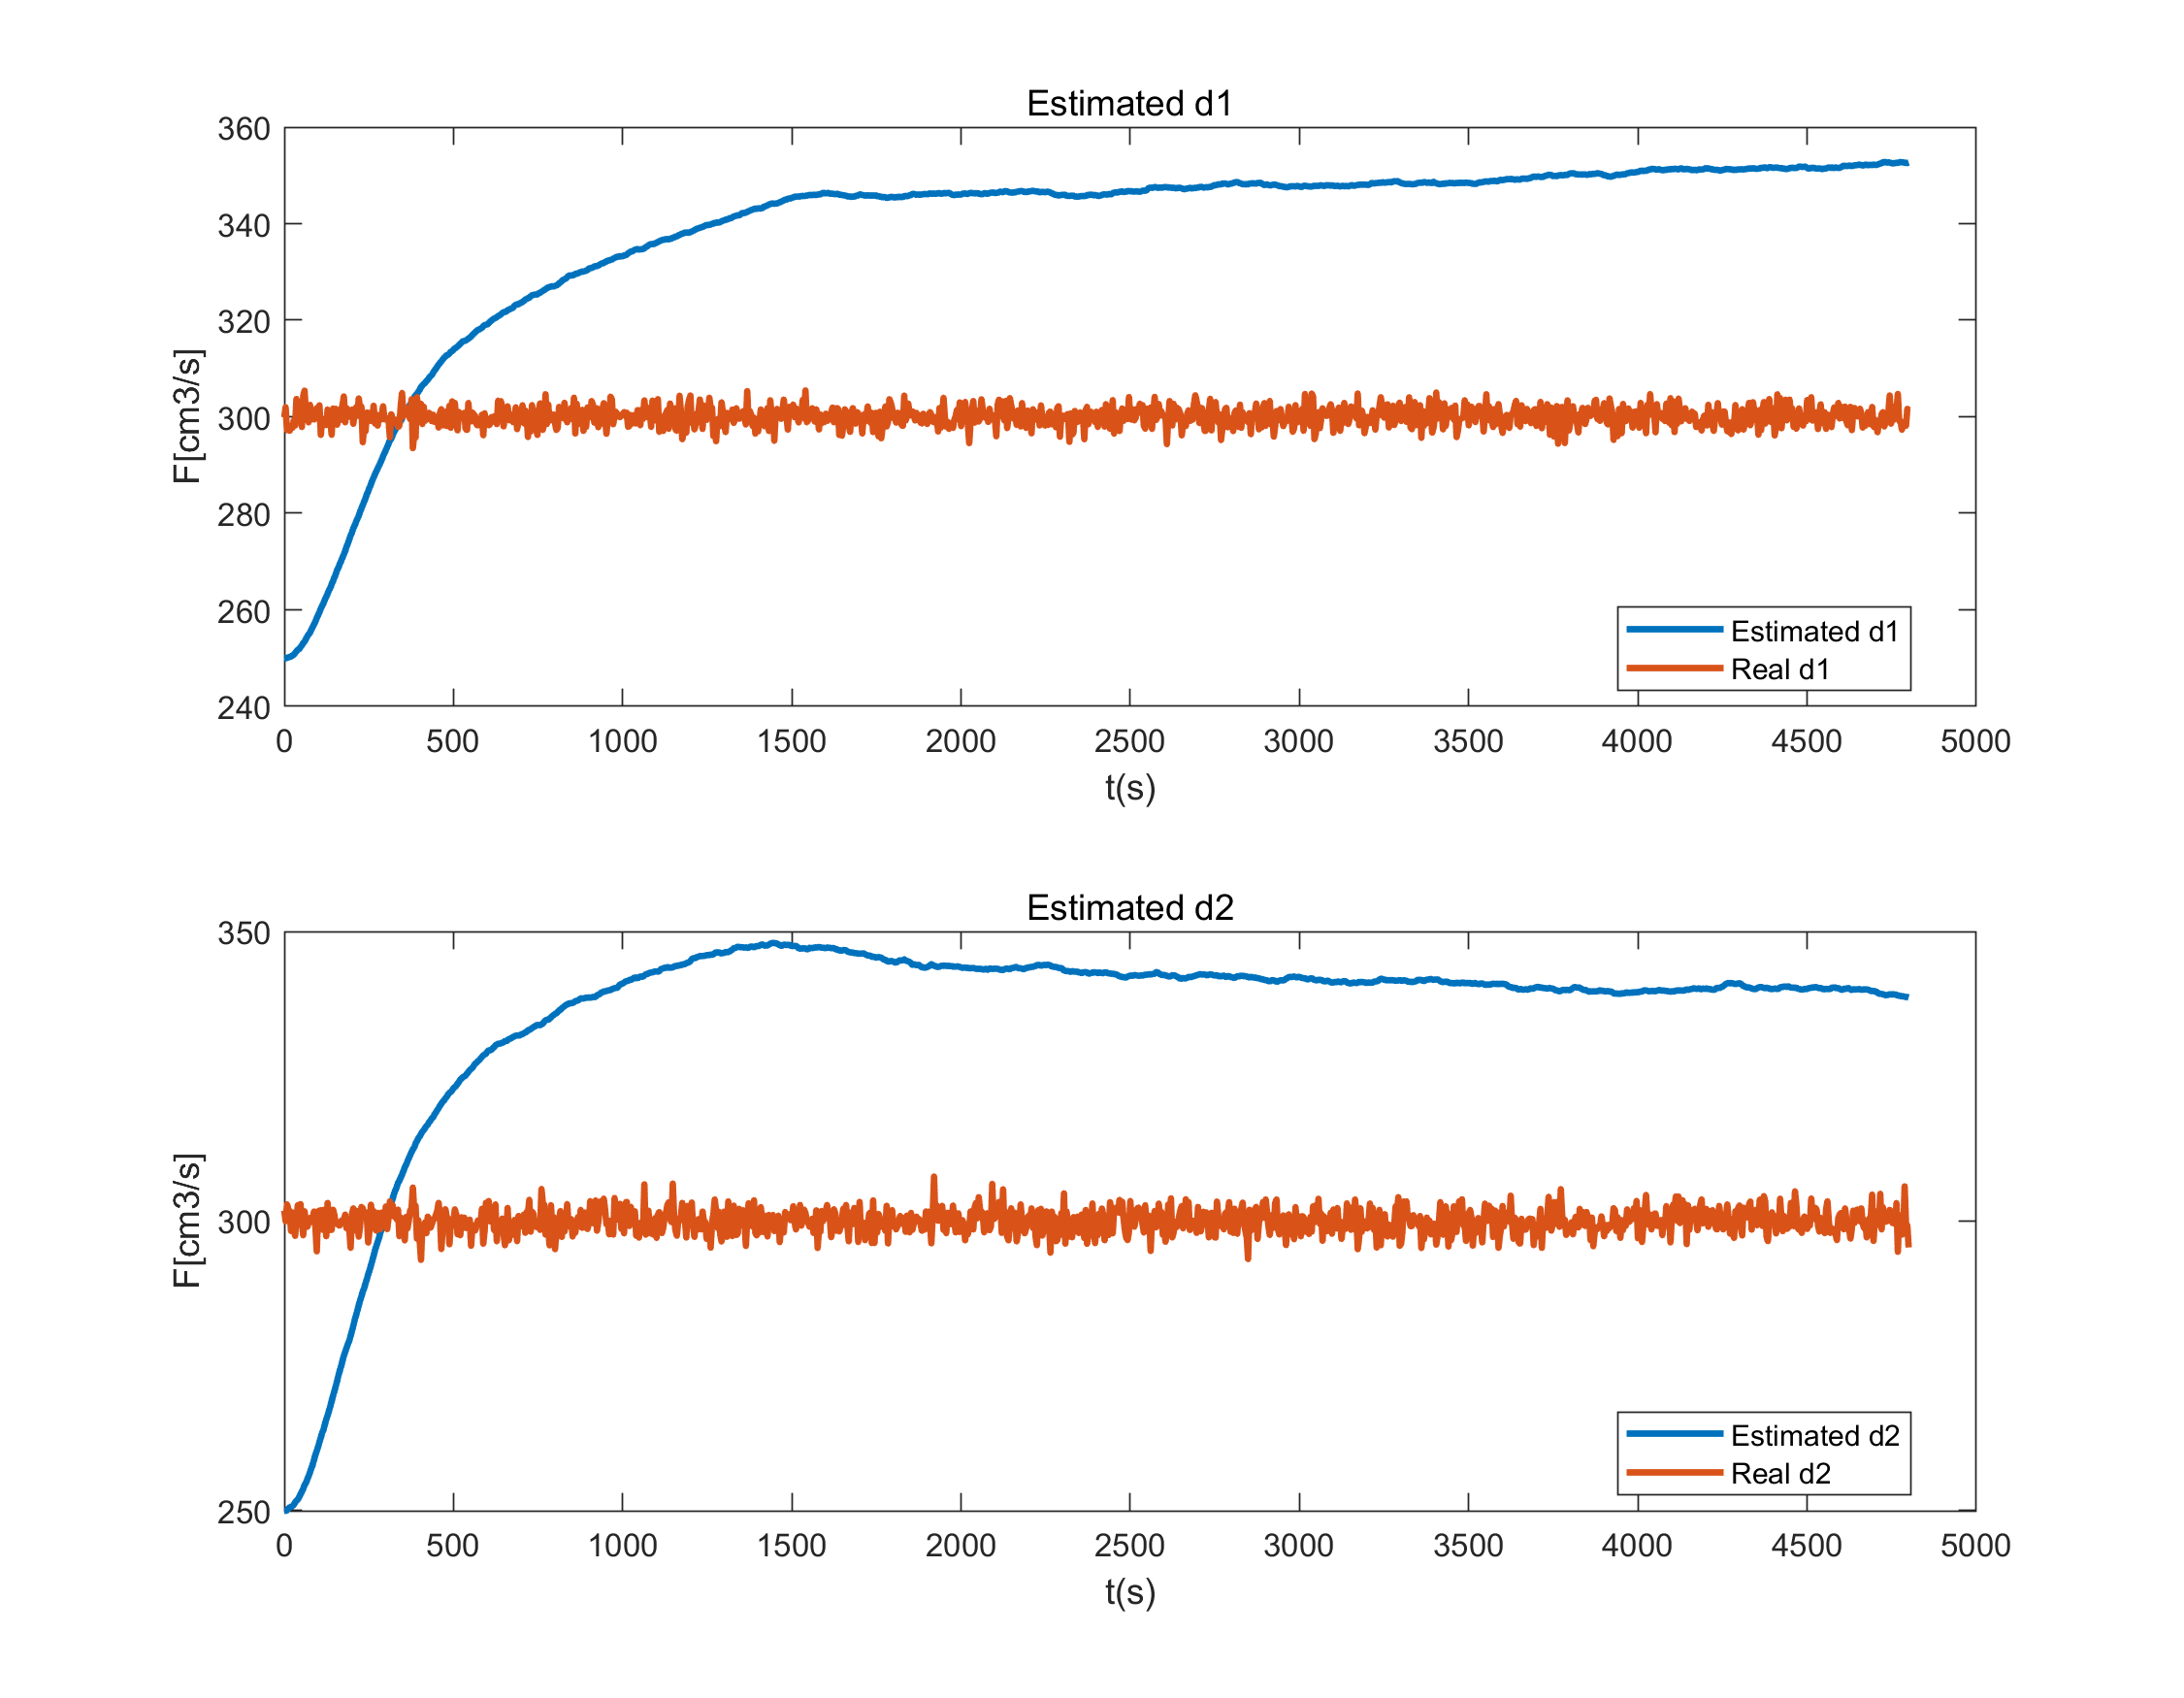

%ylim([0,40]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,d_bar(1,:)+ds(1),t,dw(1,:),'LineWidth',2.0)
title('Estimated d1')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d1","Real d1","Location", 'best');
%ylim([0,40]);
subplot(2,1,2)
plot(t,d_bar(2,:)+ds(2),t,dw(2,:),'LineWidth',2.0)
title('Estimated d2')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d2","Real d2","Location", 'best');

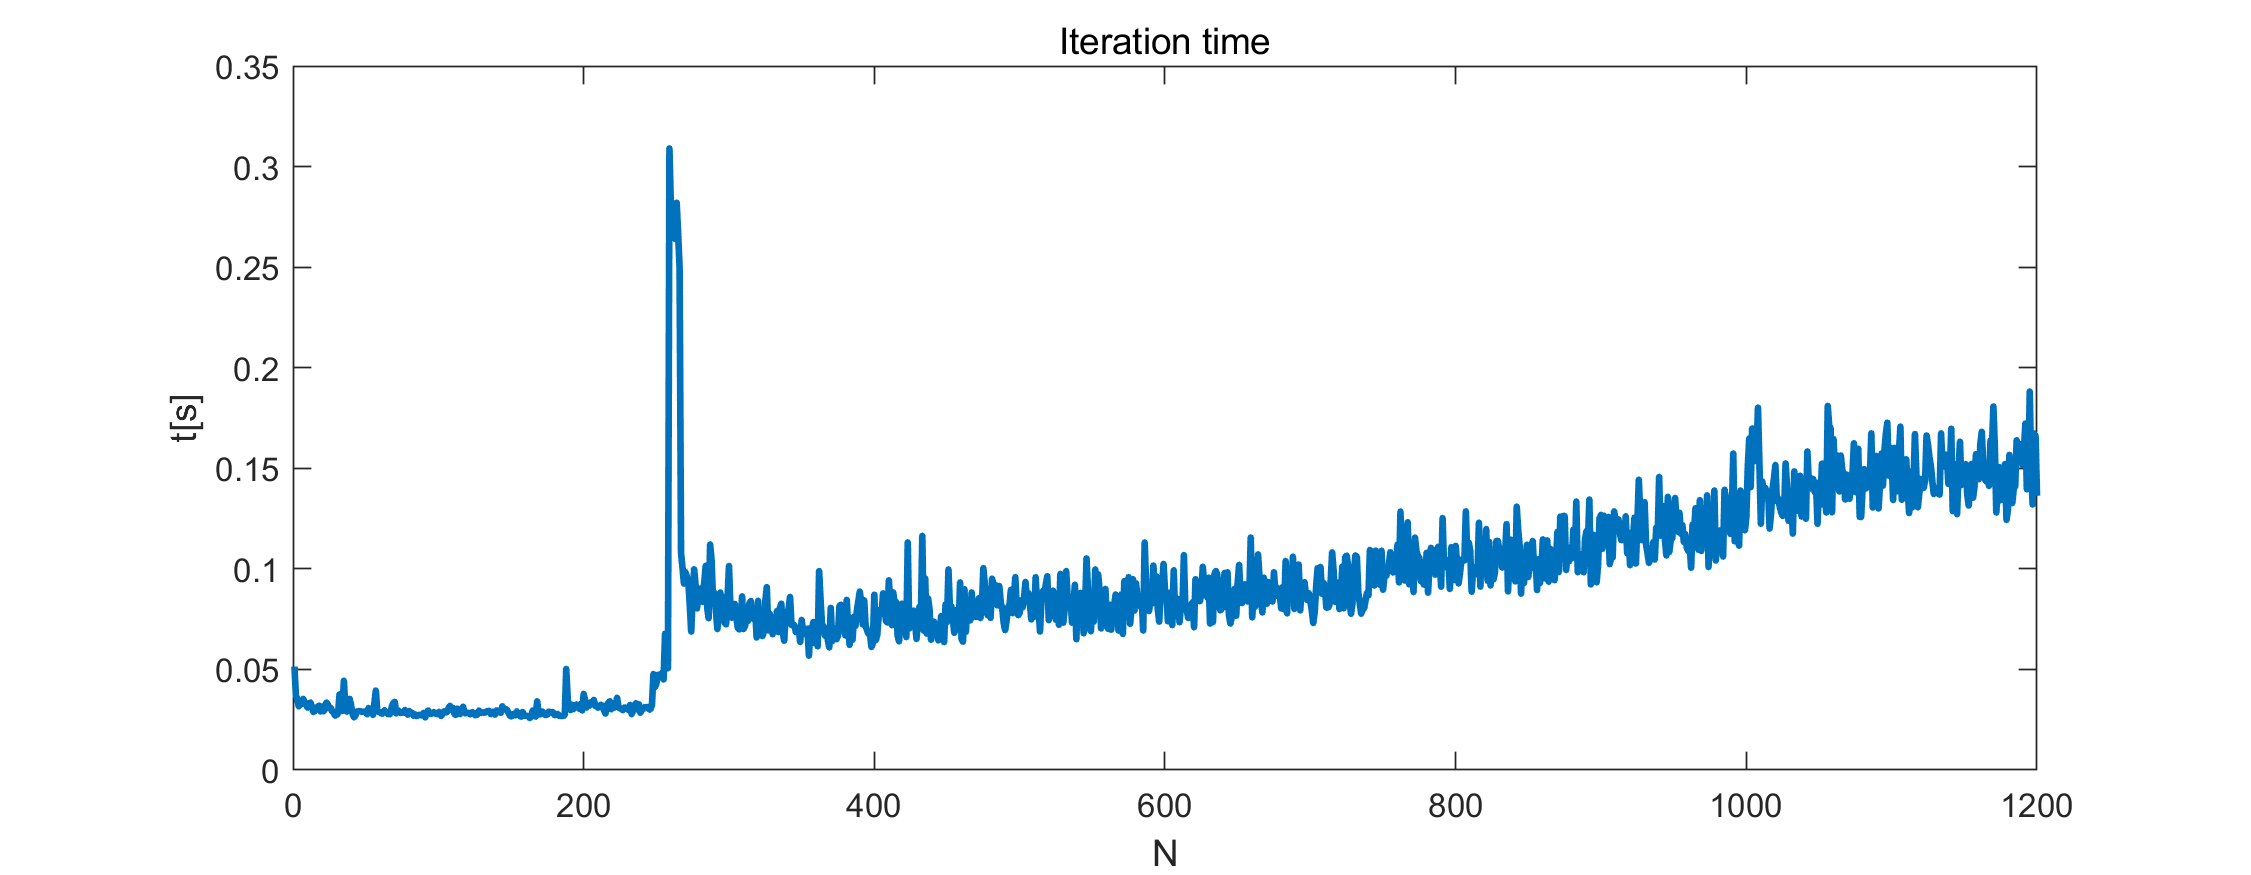


figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

%MPC with Input Constraints and Soft Output Constraints tested in nonlinear model with step of disturbance
t0 = 0.0; % [s] Initial time
t_final = 80*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Process Noise
Q = [2^2 0;0 2^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R_low = eye(4);
Lr_low = chol(R_low,'lower');
v_low = Lr_low*randn(4,N);
R_mid = 10*eye(4);
Lr_mid = chol(R_mid,'lower');
v_mid = Lr_mid*randn(4,N);
R_high = 20*eye(4);
Lr_high = chol(R_high,'lower');
v_high = Lr_high*randn(4,N);

index_step=400;
d = [repmat(300,1,N); repmat(300,1,N)];
d(1,index_step:end)=350;

dw=d+w;
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
num_eta=num_y;

ref=200;
N_pre=50;
u_min=0;
u_max=600;
u_delta_min=-30;
u_delta_max=30;
z_min=[-1000;-1000;-1000;-1000];
z_min_error=[-1000;ref-10;-1000;-1000];
z_min_safe=[0;0;0;0];
z_max=[ref+10;ref+1000;ref+1000;ref+1000];
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x_bar = zeros(num_x,N);
d_bar = zeros(num_d,N);

x0=xs;
d0=zeros(2,1);

x(:,1) = x0;
x_bar(:,1) = x0;
d_bar(:,1) = d0;
xk=x_bar(:,1);
rk=ref*ones(N_pre*num_y,1);%y1,y2,y3,y4
dk=d_bar(:,1);
uk=us;%d1,d2 ref
usk=[repmat(us(1),N_pre*num_u,1); zeros(N_pre*num_eta,1)];

x(:,1)=x0;
u(:,1)=uk;
z_flag=0;
t_record=[];
for k = 1:N-1
%%%%%%%%%%%%%%%%%%sensor feedback%%%%%%%%%%%%%%%%
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function

%%%%%%%%%%%%%%%%%%kalman observer%%%%%%%%%%%%%%%%%%
%static observer
x_kf=[x_bar(:,k);d_bar(:,k)];
u_kf=uk;
x_kf=Ad_kf*x_kf+Bd_kf*u_kf+Ad_kf*L_kf*(yk-(Cdy_kf*x_kf+Dss*u_kf));
xk = x_kf(1:num_x);
%dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
dk=x_kf(num_x+1:num_x+2);

%dynamic kalman
% P = G_w*W_kf*G_w';
% x_kf=[x_bar(:,k);d_bar(:,k)];
% u_kf=u(:,k);
% y_bar=Cdy_kf*x_kf;
% e_bar=y(:,k)-y_bar;
% R=Cdy_kf*P*Cdy_kf'+R;
% K=P*Cdy_kf'*inv(R);
% x_kf=x_kf+K*e_bar;
% P=P-K*R*K';
% x_kf=Ad_kf*x_kf+Bd_kf*u_kf;
% P=Ad_kf*P*Ad_kf'+G_w*W_kf*G_w';
% 
% %z_bar=Cz*x_kf;
% R=Cdy_kf*P*Cdy_kf';
% xk = x_kf(1:num_x);
% %dk = [repmat(X_bar(num_x+1),N_pre,1); repmat(X_bar(num_x+2),N_pre,1)];
% dk=x_kf(num_x+1:num_x+2);
%%%%%%%%%%%%%%decision making%%%%%%%%%%%%%%%%
if(yk(2)>(z_min_error(2)-10))
    z_min=z_min_error;
    z_flag=1;
else 
    z_min=z_min_safe; 
end
if(z_flag==1)
    z_min=z_min_error;
end
%%%%%%%%%%%%%%MPC controller%%%%%%%%%%%%%%%%
tic;
uk=LMPCcompute_inputcons_outputSoftCons(rk,xk,dk,uk,Ad,Bd,Bd_d,Css,u_min,u_max,u_delta_min,u_delta_max,z_min,z_max,N_pre,Q_cof,u_delta_cof,eta_cof1,eta_cof2);
elapsedTime = toc;
t_record=[t_record;elapsedTime];

u(:,k+1)=uk;
%state update
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],uk,d(:,k)+w(:,k),p);
xk=Xk(end,:)';

x(:,k+1)=xk;
y(:,k)=yk;
z(:,k)=zk;

x_bar(:,k+1) = x_kf(1:num_x);
d_bar(:,k+1) = x_kf(num_x+1:end);
end
k=N;
yk = FourTankSystemSensorNoise(x(:,k),p,v_low(:,k));% Sensor function
zk = FourTankSystemOutput(x(:,k),p); % Output function
y(:,k)=yk;
z(:,k)=zk;

figure;
width=900;
height=800;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(4,1,1)
plot(t,y(1,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y1')
legend("Output y1","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,2)
plot(t,y(2,:),t,(ref)*ones(size(t,1),1),'LineWidth',2.0)
title('Measurement of y2')
legend("Output y2","Reference","Location", 'best');
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,3)
plot(t,y(3,:),'LineWidth',2.0)
title('Measurement of y3')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);
subplot(4,1,4)
plot(t,y(4,:),'LineWidth',2.0)
title('Measurement of y4')
xlabel('t(s)');
ylabel('h[cm]');
% ylim([0,20]);



figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,u(1,:),'LineWidth',2.0)
title('Input u1')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);
subplot(2,1,2)
plot(t,u(2,:),'LineWidth',2.0)
title('Input u2')
xlabel('t(s)');
ylabel('F[cm3/s]');
%ylim([0,40]);

figure;
width=900;
height=700;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
subplot(2,1,1)
plot(t,d_bar(1,:)+ds(1),t,dw(1,:),'LineWidth',2.0)
title('Estimated d1')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d1","Real d1","Location", 'best');
%ylim([0,40]);
subplot(2,1,2)
plot(t,d_bar(2,:)+ds(2),t,dw(2,:),'LineWidth',2.0)
title('Estimated d2')
xlabel('t(s)');
ylabel('F[cm3/s]');
legend("Estimated d2","Real d2","Location", 'best');

figure;
width=900;
height=350;
left=0;
bottem=0;
set(gcf,'position',[left,bottem,width,height])
plot(t_record,'LineWidth',2.0)
title('Iteration time')
xlabel('N');
ylabel('t[s]');

